# Figure S7H

**Load Data**

clear
[file_loc] = fileparts(matlab.desktop.editor.getActiveFilename);
cd(file_loc);
dataDir = '..\..\FINAL DATA files';

load([dataDir filesep 'A058_data.mat'],'S','settings','allIF');
conditions = settings.conditions

conditions = 20×5 cell array
    {'RO DOX'     }    {[2 3 4]}    {[ 2]}    {[1]}    {[0]}
    {'2i DOX'     }    {[2 3 4]}    {[ 3]}    {[1]}    {[0]}
    {'RO+2i DOX'  }    {[2 3 4]}    {[ 4]}    {[1]}    {[0]}
    {'4/6i DOX'   }    {[2 3 4]}    {[ 5]}    {[1]}    {[0]}
    {'DMSO DOX'   }    {[2 3 4]}    {[ 6]}    {[1]}    {[0]}
    {'RO DMSO'    }    {[2 3 4]}    {[ 7]}    {[1]}    {[0]}
    {'2i DMSO'    }    {[2 3 4]}    {[ 8]}    {[1]}    {[0]}
    {'RO+2i DMSO' }    {[2 3 4]}    {[ 9]}    {[1]}    {[0]}
    {'4/6i DMSO'  }    {[2 3 4]}    {[10]}    {[1]}    {[0]}
    {'DMSO DMSO'  }    {[2 3 4]}    {[11]}    {[1]}    {[0]}
    {'500nM TAK'  }    {[5 6 7]}    {[ 2]}    {[1]}    {[0]}
    {'250nM TAK'  }    {[5 6 7]}    {[ 3]}    {[1]}    {[0]}
    {'125nM TAK'  }    {[5 6 7]}    {[ 4]}    {[1]}    {[0]}
    {'62.5nM TAK' }    {[5 6 7]}    {[ 5]}    {[1]}    {[0]}
    {'31.25nM TAK'}    {[5 6 7]}    {[ 6]}    {[1]}    {[0]}
    {'15.6nM TAK' }    {[5 6 7]}    {[ 7]}    {[1]}    {



framesPerHr = 60/12;
 frameDrugAdded =0;
frameEdU = 0;
timeStart = 0;

folding =5;

numFrames = size(S(1).area,2);
xFrames = 1:numFrames;
xTime = (xFrames-1)./framesPerHr;



times = arrayfun(@(x)(numFrames - x.POI)/framesPerHr,S,'UniformOutput',false);
[S.POI_time] = times{:};
% 
for i = 1:length(S)
    S(i).frameDrugAdded = conditions{i,5};
    S(i).POI_realtime = S(i).POI/framesPerHr;
    S(i).POI_drug_time = ( S(i).frameDrugAdded - S(i).POI)/framesPerHr;
   S(i).drug_time = S(i).frameDrugAdded/framesPerHr;
end

 drug_time = frameDrugAdded/framesPerHr;

S7H

conds = [10 8 3 ];
figure('unit','inches','position',[0 0 4 4])
yval = 'RFP2';
cols =  [.5 .5 .5;0 0 1;  1 .5 .2; 0 .4 .6; .855 .384 1;0 0 1];
gateVals = {'dna'};
rangeVals = {[.3e6 1.5e6]}; 

figure, hold on
for i = 1:length(conds)
    condition = conds(i);
    ydata = real(log2(S(condition).(yval))); %.*S(condition).area);

    totalGate = true(size(ydata,1),1);
    for gate = 1:size(gateVals,2)
        gateInds = S(condition).(gateVals{gate})<rangeVals{gate}(2) & S(condition).(gateVals{gate})>rangeVals{gate}(1);
        totalGate = totalGate  & gateInds;
    end
    
    ydata = ydata(totalGate);
    length(ydata)
   edges = linspace(5,15,20);
    
    [N,~] = histcounts(ydata,edges);
    plot(edges(2:end),N/length(ydata),'Linewidth',2,'color',cols(i,:));
    
end

ans = 3527

ans = 254

ans = 180

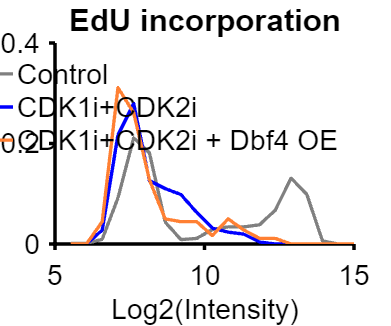

legend('Control','CDK1i+CDK2i','CDK1i+CDK2i + Dbf4 OE','fontsize',17,'box','off');
xlabel('Log2(Intensity)')
hold off
title('EdU incorporation')
ylim([0,.4])
set(gca,'FontSize',17)

% print_pdf(['fig_S7H.pdf'])